# Forward Kinematic

Consider the Universal Robots ur3: 

we want to compute the position and orientation in 3D space of a certain joint configuration in regards to the home position. 

Let the configuration be: 

JointState=[pi/2, -pi/2, 0, 0, pi/2, pi]

JointState =     1.5708   -1.5708         0         0    1.5708    3.1416


%JointState=zeros(1,6)

DH=[ %by Universal Robots (website)
   %a       alpha       d       theta
   0        pi/2        0.1519  0;
   -0.24365 0           0       0;
   -0.21325 0           0       0;
   0        pi/2        0.11235 0;
   0        -pi/2       0.08535 0;
   0        0           0.0819  0;
    ]

DH =          0    1.5708    0.1519         0
   -0.2437         0         0         0
   -0.2132         0         0         0
         0    1.5708    0.1124         0
         0   -1.5708    0.0853         0
         0         0    0.0819         0




ThetaOffset=DH(:,4); 


## Symbolic Math Toolbox

We can also model the Robot using the Symbolic Math Toolbox. This allows us to define Transform matrices using symbolic variables and substituting the real values later. 

Lets understand how the Transform matrix works: 

For DH modeling we have two homogeneous transforms and two rotations. Following these steps results in the following: 

syms alpha theta a d real %setup symbolic variables and define them as real (no complex numbers) 

The DH parameter work in this order: 

- align direction of the common normal (x-axis) using theta (for revolute joints this is the input q).

- translation along x_axis (common normal) with a. This will allign both origins to the same Y-Z plane.

- translation along the z-axis with d. This will put the origin of the coordinate systems in the same point. (for prismatic joints this will be input q) 

- rotation around x-axis to allign z axis with alpha.

fourbyfour=sym(eye(4)); %This gives us an identity matrix of size 4x4. We convert it to symbolic to be able to combine it with the rotations

$$fourbyfour = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

FirstRotation=fourbyfour; 
FirstRotation(1:3,1:3)=rotz(theta) %only fill the top left 3x3 matrix --> Rotate around z axis

$$FirstRotation = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


FirstTranslation=transl([a 0 0]) %create a 4x4 translation matrix --> Move along x axis

$$FirstTranslation = \left(\begin{array}{cccc} 1 & 0 & 0 & a\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


SecondTranslation=transl([0 0 d]) %create a 4x4 translation matrix --> move along z axis 

$$SecondTranslation = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$


SecondRotation=fourbyfour; 
SecondRotation(1:3,1:3)=rotx(alpha) %only fill the top left 3x3 matrix to get a 4x4 matrix --> rotate around x axis

$$SecondRotation = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$



Ai=FirstRotation*FirstTranslation*SecondTranslation*SecondRotation

$$Ai = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$


Ai_symbolic = [
                  cos(theta)     -sin(theta)*cos(alpha)    sin(theta)*sin(alpha)     a*cos(theta);
                  sin(theta)     cos(theta)*cos(alpha)     -cos(theta)*sin(alpha)    a*sin(theta);
                  0              sin(alpha)                cos(alpha)                d;
                  0              0                         0                         1
              ]

$$Ai\_symbolic = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Let us visualize what is happening with these transforms

          %theta     d       a       alpha
DHexample=[pi/2,    0.24,   0.6,    -pi/2]

DHexample =     1.5708    0.2400    0.6000   -1.5708


exampleFirstRotation=subs(FirstRotation,theta,DHexample(1));
exampleFirstTranslation=subs(FirstTranslation,a,DHexample(2));
exampleSecondTranslation=subs(SecondTranslation,d,DHexample(3));
exampleSecondRotation=subs(SecondRotation,alpha,DHexample(4));

M=zeros(4,4,5)

M = M(:,:,1) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


M(:,:,2) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


M(:,:,3) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


M(:,:,4) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


M(:,:,5) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


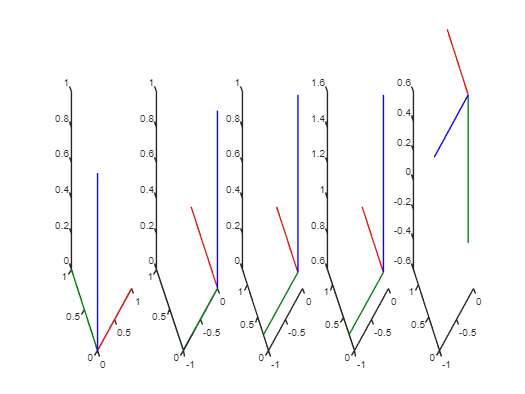

M(:,:,1)=eye(4); 
M(:,:,2)=M(:,:,1)*double(exampleFirstRotation); 
M(:,:,3)=M(:,:,2)*double(exampleFirstTranslation); 
M(:,:,4)=M(:,:,3)*double(exampleSecondTranslation);
M(:,:,5)=M(:,:,4)*double(exampleSecondRotation); 

figure; 
axis(2*[-1,1,-1,1,-1,1])
for i=1:5
subplot(1,5,i)
plotTransforms(M(1:3,4,i)',tform2quat(M(:,:,i)))
end


clear DHexample exampleFirstRotation exampleSecondRotation exampleSecondTranslation exampleFirstTranslation M

We can easily substitute the actual values from our DH parameter table for the symbolic variables using MATLABS subs() function. Lets say we want to compute the Transformation Matrix from link 0 to 1 of the previously defined DH table belonging to the UR3 Robot. Remember that we have a Revolute joint. For this reason we need to define a new symbolic variable q1 that describes the joint angle and add it to the offset (home configuration). We will call this Matrix A01.

syms q1 q2 q3 q4 q5 q6 real
q=[q1 q2 q3 q4 q5 q6];
A01=subs(Ai,{a alpha d theta},{[DH(1,1:3),q(1)]})

$$A01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & \frac{1519}{10000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12=subs(Ai,{a alpha d theta},{[DH(2,1:3),q(2)]})

$$A12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & -\frac{4873\,\cos\left(q_{2}\right)}{20000}\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & -\frac{4873\,\sin\left(q_{2}\right)}{20000}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23=subs(Ai,{a alpha d theta},{[DH(3,1:3),q(3)]})

$$A23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & -\frac{853\,\cos\left(q_{3}\right)}{4000}\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & -\frac{853\,\sin\left(q_{3}\right)}{4000}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A34=subs(Ai,{a alpha d theta},{[DH(4,1:3),q(4)]})

$$A34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & 0 & \sin\left(q_{4}\right) & 0\\ \sin\left(q_{4}\right) & 0 & -\cos\left(q_{4}\right) & 0\\ 0 & 1 & 0 & \frac{2247}{20000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A45=subs(Ai,{a alpha d theta},{[DH(5,1:3),q(5)]})

$$A45 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & 0 & -\sin\left(q_{5}\right) & 0\\ \sin\left(q_{5}\right) & 0 & \cos\left(q_{5}\right) & 0\\ 0 & -1 & 0 & \frac{1707}{20000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A56=subs(Ai,{a alpha d theta},{[DH(6,1:3),q(6)]})

$$A56 = \left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & 0\\ \sin\left(q_{6}\right) & \cos\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{819}{10000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A06=A01*A12*A23*A34*A45*A56



vpa(subs(A01,q1,0),4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0\\ 0 & 0 & -1.0 & 0\\ 0 & 1.0 & 0 & 0.1519\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(subs(A12,q2,0),4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & -0.2436\\ 0 & 1.0 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(subs(A23,q3,0),4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & -0.2132\\ 0 & 1.0 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(subs(A34,q4,0),4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0\\ 0 & 0 & -1.0 & 0\\ 0 & 1.0 & 0 & 0.1124\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(subs(A45,q5,0),4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & -1.0 & 0 & 0.08535\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(subs(A56,q6,0),4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0\\ 0 & 1.0 & 0 & 0\\ 0 & 0 & 1.0 & 0.0819\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$


A06_home=vpa(subs(A06,{q1,q2,q3,q4,q5,q6},{[0,0,0,0,0,0]}),4)

$$A06\_home = \left(\begin{array}{cccc} 1.0 & 0 & 0 & -0.4569\\ 0 & 0 & -1.0 & -0.1943\\ 0 & 1.0 & 0 & 0.06655\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$


getTransform(ur3, ur3home, "base_link","tool0")

ans =    -1.0000         0   -0.0000    0.4569
   -0.0000    0.0000    1.0000   -0.0665
    0.0000    1.0000   -0.0000   -0.1942
         0         0         0    1.0000


## Robotic System Toolbox

ur3=loadrobot("universalUR3")

ur3 =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base_link'  'base'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'ee_link'  'tool0'}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'struct'


ur3home=homeConfiguration(ur3); 

allignment=fourbyfour; 
allignment(1:3,1:3)=rotx(-pi/2);

vpa(getTransform(ur3,ur3home,"base","ee_link"),4)

$$ans = \left(\begin{array}{cccc} 1.0 & 2.068e-13 & -9.793e-12 & 0.4569\\ 2.068e-13 & -1.0 & 0 & -0.1124\\ -9.793e-12 & -2.025e-24 & -1.0 & 0.06655\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

We can visualize this configuration as

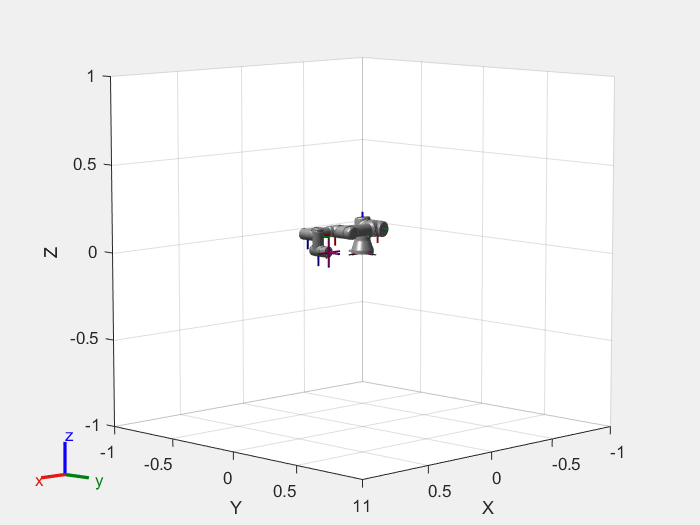

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


figure(Name='UR3 joint configuration'); 
show(ur3,ur3home) 

## Trying to get Transformation Matrix from Toolbox

A06_toolbox=eye(4);
for i=1:8
    disp(i)
    ur3.Bodies{1,i}.Joint.JointToParentTransform
    A06_toolbox=A06_toolbox*ur3.Bodies{1,i}.Joint.JointToParentTransform
    try
    getTransform(ur3,ur3home,string(ur3.BodyNames(i-1)),string(ur3.BodyNames(i)))
    end
end

     1



ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Atest =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


     2



ans =    -1.0000   -0.0000         0         0
    0.0000   -1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


Atest =    -1.0000   -0.0000         0         0
    0.0000   -1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


ans =    -1.0000    0.0000         0         0
   -0.0000   -1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


     3



ans =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.1519
         0         0         0    1.0000


Atest =    -1.0000   -0.0000         0         0
    0.0000   -1.0000         0         0
         0         0    1.0000    0.1519
         0         0         0    1.0000


ans =    -1.0000   -0.0000         0         0
    0.0000   -1.0000         0         0
         0         0    1.0000   -0.1519
         0         0         0    1.0000


     4



ans =     0.0000         0    1.0000         0
         0    1.0000         0    0.1198
   -1.0000         0    0.0000         0
         0         0         0    1.0000


Atest =    -0.0000   -0.0000   -1.0000   -0.0000
    0.0000   -1.0000    0.0000   -0.1198
   -1.0000         0    0.0000    0.1519
         0         0         0    1.0000


ans =     0.0000         0   -1.0000         0
         0    1.0000         0   -0.1198
    1.0000         0    0.0000         0
         0         0         0    1.0000


     5



ans =     1.0000         0         0         0
         0    1.0000         0   -0.0925
         0         0    1.0000    0.2437
         0         0         0    1.0000


Atest =    -0.0000   -0.0000   -1.0000   -0.2437
    0.0000   -1.0000    0.0000   -0.0273
   -1.0000         0    0.0000    0.1519
         0         0         0    1.0000


ans =     1.0000         0         0         0
         0    1.0000         0    0.0925
         0         0    1.0000   -0.2437
         0         0         0    1.0000


     6



ans =     0.0000         0    1.0000         0
         0    1.0000         0         0
   -1.0000         0    0.0000    0.2132
         0         0         0    1.0000


Atest =     1.0000   -0.0000   -0.0000   -0.4569
   -0.0000   -1.0000    0.0000   -0.0273
   -0.0000         0   -1.0000    0.1519
         0         0         0    1.0000


ans =     0.0000         0   -1.0000    0.2132
         0    1.0000         0         0
    1.0000         0    0.0000   -0.0000
         0         0         0    1.0000


     7



ans =     1.0000         0         0         0
         0    1.0000         0    0.0851
         0         0    1.0000         0
         0         0         0    1.0000


Atest =     1.0000   -0.0000   -0.0000   -0.4569
   -0.0000   -1.0000    0.0000   -0.1123
   -0.0000         0   -1.0000    0.1519
         0         0         0    1.0000


ans =     1.0000         0         0         0
         0    1.0000         0   -0.0851
         0         0    1.0000         0
         0         0         0    1.0000


     8



ans =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.0853
         0         0         0    1.0000


Atest =     1.0000   -0.0000   -0.0000   -0.4569
   -0.0000   -1.0000    0.0000   -0.1123
   -0.0000         0   -1.0000    0.0666
         0         0         0    1.0000


ans =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000   -0.0853
         0         0         0    1.0000


A06_toolbox=A06_toolbox*ur3.Bodies{1,10}.Joint.JointToParentTransform

Atest =     1.0000    0.0000   -0.0000   -0.4569
   -0.0000   -0.0000   -1.0000   -0.1942
   -0.0000    1.0000   -0.0000    0.0666
         0         0         0    1.0000
